**Traslación en el Tiempo**

%%Aplicando las propiedades 
clear all;
close all;
clc;

%Transformada de Fourier
fs = 900; %frecuencia muestreo
ts=1/fs;
T =4; % ancho del pulso
tao=0;%para traslaciòn en el tiempo
t=-T/2+tao:ts:T/2+tao; 
x=rectpuls(t,T);
b=1;%punto de corte con el eje
A=13;
xt=(((4/3)*(t-A))-2/3);%Funcion de entrada

N = (2^(nextpow2(10*length(xt))));
Xf=abs(fftshift(fft(xt,N)))/fs;% Transformada FFT
f = linspace(-0.5*fs,0.5*fs,length(Xf));

%subplot(2,1,1);plot(t,xt);grid
plot(t,xt);grid
title('Señal de entrada');
figure();
%subplot(2,1,2);plot(f,Xf);grid %xlim([-3 3])
plot(f,Xf);grid ;xlim([-5 5])
title('Espectro');

**Traslación en el tiempo**

%%Aplicando las propiedades 
clear all;
close all;
clc;
%Traslación en el tiempo
Fs = 1000;       %Frecuencia de muestreo
t = -1:1/Fs:2;  %Vector de tiempo  t=-T/2+tao:ts:T/2+tao;
L = 2000;       %Longitud de la señal 
A=2;
Tras_t =(((4/3)*(t-A))-2/3);%S
Y= fft(Tras_t,L);    %Transformada rápida

P = abs(Y/Fs);
f = linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica fft')
xlabel('Frecuencia')
ylabel('|P(f)|')

syms t f; 

x=(((4/3)*(t-A))-2/3);  %
Tras_t=int(x*exp(-1i*2*pi*f*t),t,-1,2); %Transformada de Fourier teórica

$$Tras\_t = -\frac{{\mathrm{e}}^{-4\,\pi \,f\,\mathrm{i}}\,\left({\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}-1+\pi \,f\,\mathrm{i}-7\,\pi \,f\,{\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}\,\mathrm{i}\right)}{3\,f^{2}\,\pi^{2}}$$

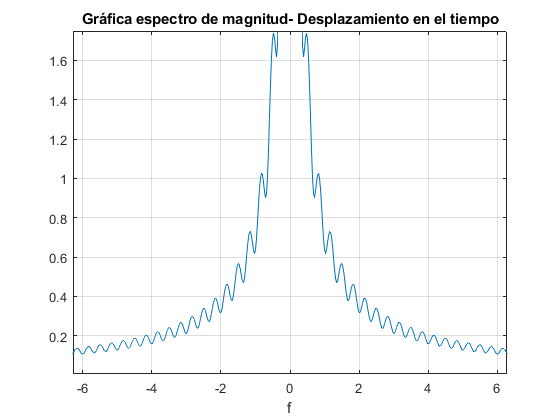

%hold on         %sobreposición
% fplot(f,abs(Tras_t))
% figure

%-----Gráfica espectro de magnitud
ezplot(abs(Tras_t));z
title('Gráfica espectro de magnitud teorico- Desplazamiento en el tiempo')
grid on